## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close

%% Load data
load area_rating_curve.txt
load kc.txt % [-]
load P.txt % [mm/h]
load Q_obs.txt %[m^3/s]
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7*3600;   %[m^3/h] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000*10^6;  %[m^2] Catchment area
phi = 38;       %[°] Latitude 


%% Power plant parameters
Q_T =35*3600;           %m^3/h turbine discharge
D_pipe = 3.3;                %pipe diameter [m]
L_pipe = 1200;             %pipe length [m]
ks = 0.0005;            %pipe roughness [m]
eta = 0.73;             %turbines efficiency [-]
delta_z_empty = 75;           %difference of elevation between the empty pool level and the level of the tailrace [m]
lmin_HU = 7;            %minimum level for hydropower production with respect to the empty pool level [m]
nu = 1.79 * 10^-5;   % water kinematic viscosity [m/s^2]
rho = 1000;   %water density [kg/m^3]

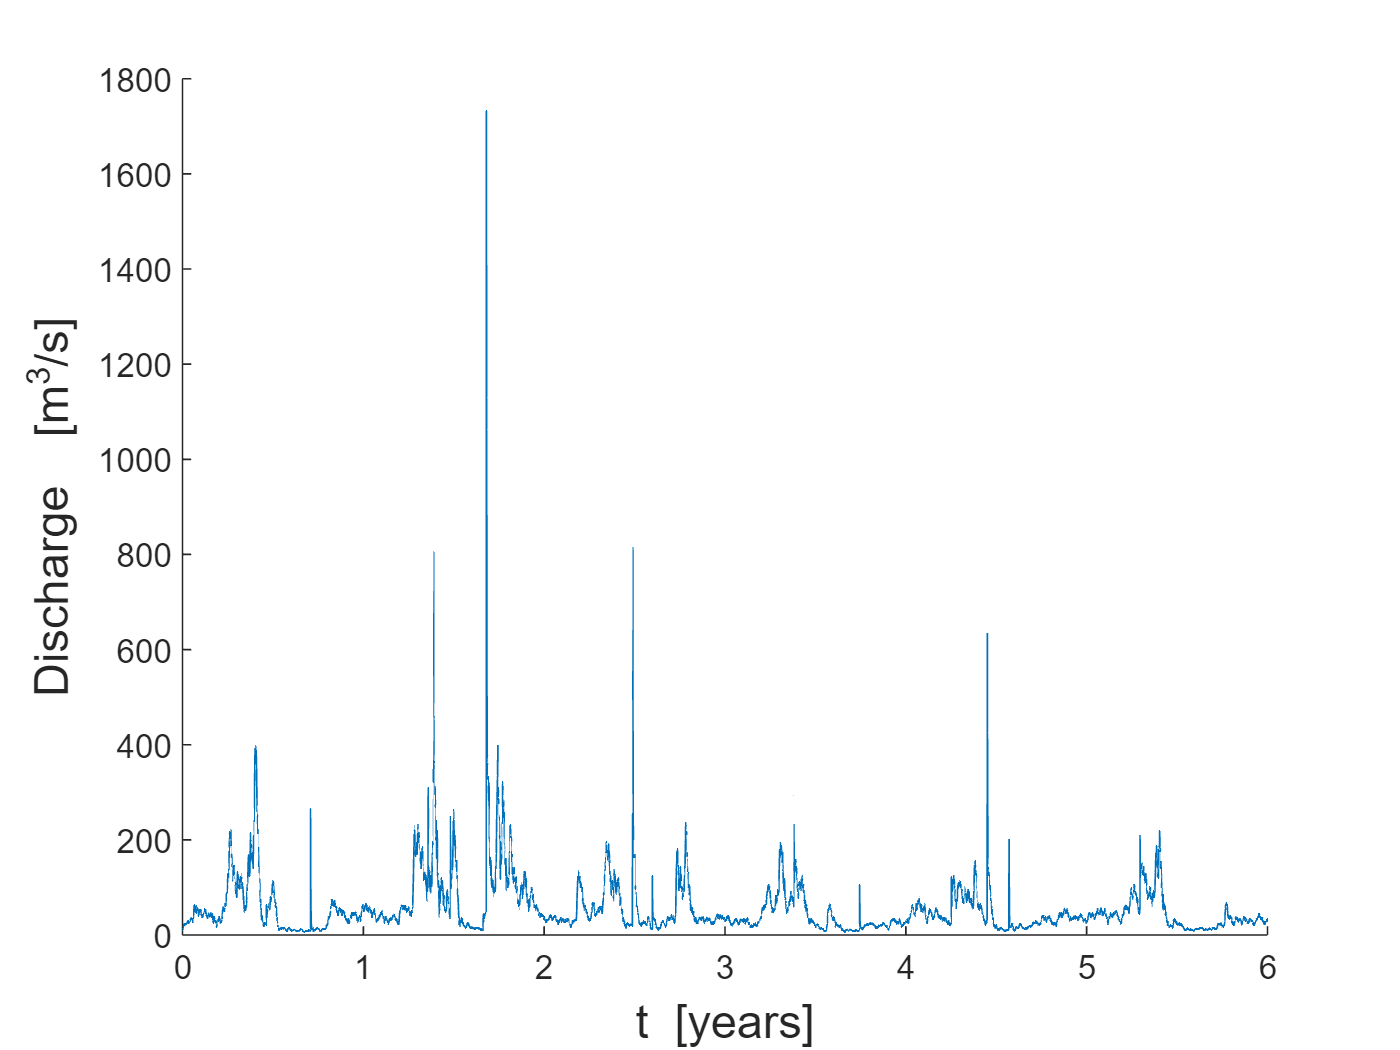

%% Plot discharge time series
figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

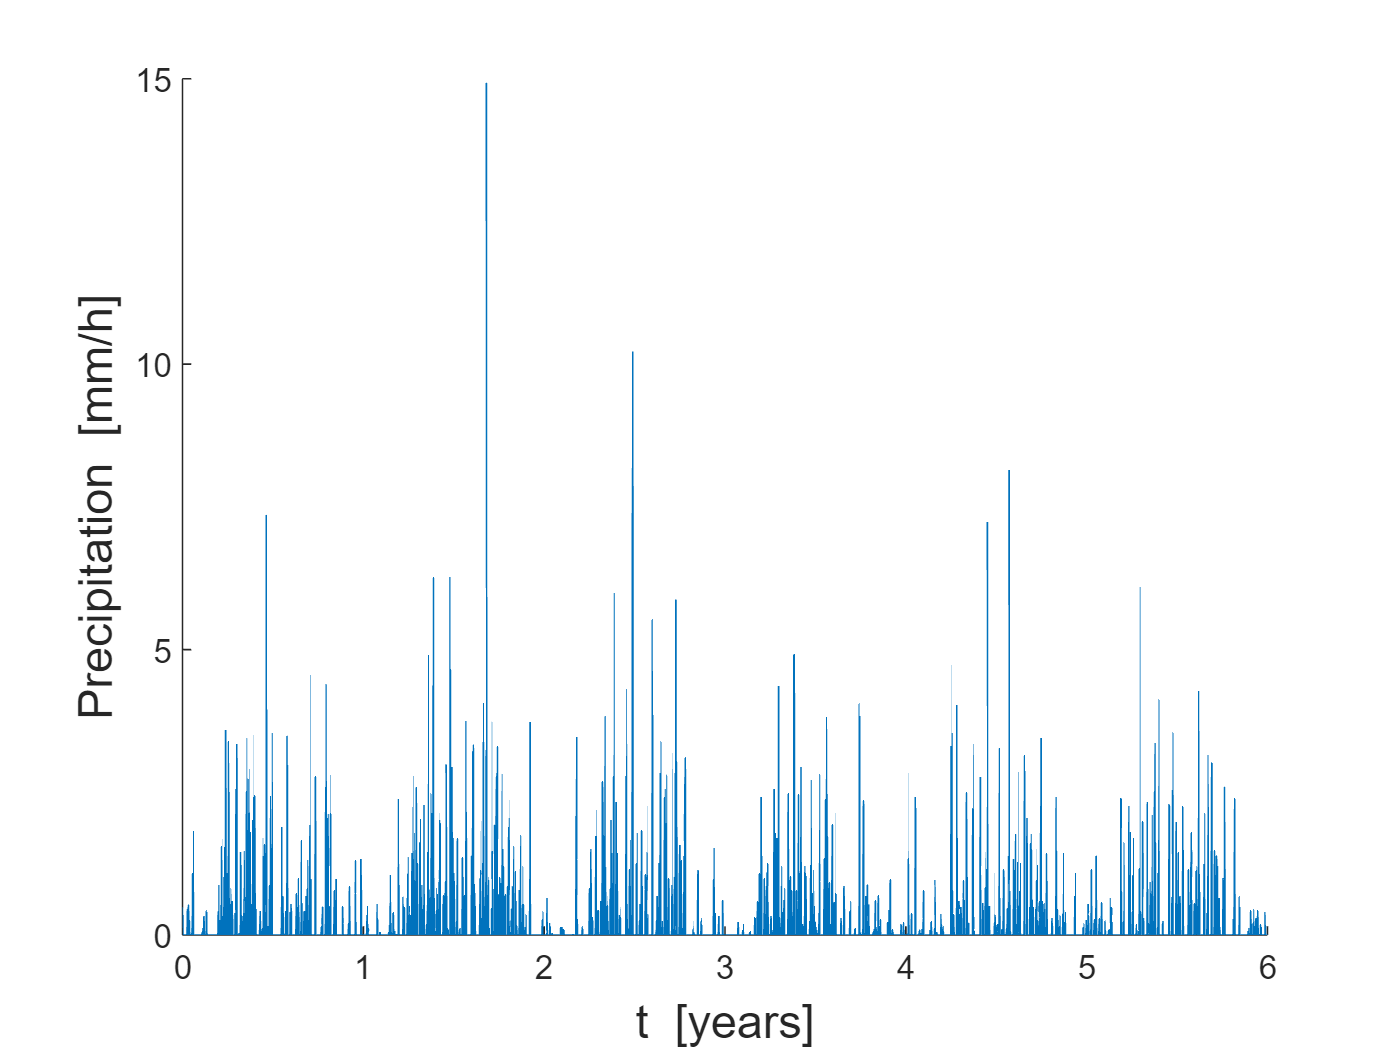


%% Plot precipitation time series
figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [mm/h]','FONTSIZE',14)      %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I = sum((temperature./5).^(1.514));
a = 6.75e-7*I^3-7.71e-5*I^2+1.79e-2*I+0.49; %experimental exponent
D = 1:365;
delt = 0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delt));
N_D = 24*w_s/pi;                            %number of daylight hours of day D
N_M =zeros(12,1);                           % mean daylight hours per day of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = (16.*(N_M/12).*(10*temperature/I).^a);   % [mm/h/unit area]
mean_monthly_ET0=ET_0./day_month';              %potential evapotranspiration in mm/day ; monthly
mean_monthly_ET0_hour=ET_0./day_month'/24/1000; % mean potential evapotranspiration in m/hour ; monthly

### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 10^(-6)*3600;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [m/s]
c = 10;                  %[-] Exponent for power-law relation L(s)  1<c<20
z = 1;           %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;             %[T] Mean sub-superficial residence time 1<t_sub<400 [h]
delta = [K_sat, c, z, t_sub];

% K_sat = 23.1423
% c = 16.4239
% z = 628.5144
% t_sub = 329.4774

% K_sat=0.0034; %m/h  
% c=6.8311;
% t_sub= 64.5218; %h
% z=0.5811; %m
% delta = [K_sat, c, z, t_sub];

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

### 4. Test the mass balance of your system in order to ensure a correct implementation.

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.

[Q_mod,R,I, s] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A,1);

NS_old = NS_fun(Q_obs*3600,Q_mod)

NS_old = 0.6517


%Q_mod = Q_mod/(60*60) ;

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

K_sat = 10^(-6)*3600;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [m/s]
c = 10;                  %[-] Exponent for power-law relation L(s)  1<c<20
z = 1;           %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;             %[T] Mean sub-superficial residence time 1<t_sub<400 [h]
delta = [K_sat, c, z, t_sub];

ranges = [0.99^(-5)*(3600),19,1999/1000,399];
upper_lim = [10^(-5)*(3600),20,2000/1000,400];
lower_lim = [10^(-7)*(3600),1,1/1000,1];
sigma = 5/100;
cr = 1/1200;

[Q_mod,R,I] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A,0);

NS_old = NS_fun(Q_obs*3600,Q_mod)

NS_old = 0.6517

% delta_old=delta;
% delta_new=delta;
% 
% Niter=1000;
% niter = 1 ; 
% while niter<Niter
%     for i=1:length(delta)
%         delta_new(i)=TruncNormRnd(delta_old(i),sigma*delta_old(i),lower_lim(i),upper_lim(i));
%     end
%     [Q_mod,R,I] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A,0);
%     NS_new = NS_fun(Q_obs*3600,Q_mod) ;
%     
%     if NS_new>NS_old
%         delta_old = delta_new;
%         NS_old = NS_new;
% 
%     else
%         r = rand;
%         if r<exp((NS_new-NS_old)/t_sa(cr,niter))
%             NS_old = NS_new;
%         end
%     end
%     if NS_new >=0.87
%         break
%     end
%     niter=niter+1;
% end

### 3. Select a new parameter set by drawing from a truncated normal distribution centered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;
ls = [];
T_SA = [];
NS = [];

Niter=1000;
niter = 1 ; 
ii = 0;
while niter<Niter
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma*delta_old(i),lower_lim(i),upper_lim(i));
    end
    [Q_mod,R,I, s, ET, L] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A,0);
    NS_new = NS_fun(Q_obs*3600,Q_mod);

    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;
        ii = ii +1 ;
        ls(ii,:) = delta_new;
        T_SA(ii) = t_sa(cr, niter);
        NS(ii) = NS_old;
        
    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,niter))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.87
        break
    end
    
    niter=niter+1;
end

'makedist' requires one of the following:
  Simulink Design Optimization
  Statistics and Machine Learning Toolbox

Error in TruncNormRnd (line 4)
t=truncate(makedist('normal',mu,sigma),l,u);

## ** Deliverables 1 and 2**

**New set of best fit parameters for the hydrological model**

disp(['ksat = ', num2str(delta_new(1)), ' ; c_new = ', num2str(delta_new(2)), ' ; z_new = ', num2str(delta_new(3)), ' ; t_sub_new = ', num2str(delta_new(4))])

**Plot the time series (6-year-long) of precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the given precipitation).**

figure(3)                                          
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('P  [mm/h]','FONTSIZE',14)   
box off
figure(4)                                          
plot((1:length(R))/(365*24),R);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('R  [mm/h]','FONTSIZE',14)   
box off

figure(5)                                          
plot((1:length(I))/(365*24),I);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('I  [mm/h]','FONTSIZE',14)   
box off
figure(6)                                          
plot((1:length(s))/(365*24),s);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('s, soil moisture  [mm/h]','FONTSIZE',14)   
box off
figure(7)                                          
plot((1:length(L))/(365*24),L);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('L  [mm/h]','FONTSIZE',14)   
box off
figure(8)                                          
plot((1:length(ET))/(365*24),ET);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('ET  [mm/h]','FONTSIZE',14)   
box off

**Deliverable 3** 

Plot the time series of observed discharge and of the discharge as simulated by the hydrological model with the best fit parameters. 

%Q_mod m3/h
%Q_obs m3/s

figure                                            
plot((1:length(Q_mod))/(365*24),Q_mod/3600);
hold on
plot((1:length(Q_obs))/(365*24),Q_obs);
hold off
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Discharge  [m^{3}/h]','FONTSIZE',14)   
legend('Q\_mod', 'Q\_obs')
box off 

**Deliverable 4**

Plot Markov chains of the calibrated parameters and sequences of values of NS and TSA as a function of the number of iterations. Only plot accepted parameter sets. 

figure                                            
plot((1:length(ls)),ls(:,1));
xlabel('niter','FONTSIZE',14)                 
ylabel('K sat  ','FONTSIZE',14)   
box on 
figure                                            
plot((1:length(ls)),ls(:,2));
xlabel('niter','FONTSIZE',14)                 
ylabel('c  ','FONTSIZE',14)   
box on 
figure                                            
plot((1:length(ls)),ls(:,3));
xlabel('niter','FONTSIZE',14)                 
ylabel('z','FONTSIZE',14)   
box on 
figure                                            
plot((1:length(ls)),ls(:,4));
xlabel('niter','FONTSIZE',14)                 
ylabel('t sub','FONTSIZE',14)   
box on 
figure                                            
plot((1:length(T_SA)),T_SA);
xlabel('niter','FONTSIZE',14)                 
ylabel('T SA','FONTSIZE',14)   
box on 
figure                                            
plot((1:length(NS)),NS);
xlabel('niter','FONTSIZE',14)                 
ylabel('NS','FONTSIZE',14)   
box on

## Simulated discharge sequence

Run the calibrated hydrological model forced by the generated rainfall and obtain the discharge time series that will constitute the input of the reservoir.

file = matfile("P_hourly.mat");
P_HOURLY = file.P_HOURLY;

[Q_simulated,R,I] = hydrological_model(P_HOURLY/1000, mean_monthly_ET0_hour, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A,0);

figure                                             
plot((1:length(Q_simulated))/(365*24),Q_simulated);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Discharge  [m^{3}/h]','FONTSIZE',14)       
box off 

## Reservoir routing and flood control

### 1. Compute the minimum flow target Q347

sort_Q=sort(Q_simulated,'descend');
p_exceedence=(1:length(Q_simulated))/length(Q_simulated);
figure
semilogy(p_exceedence,sort_Q)
title('Discharge Duration Curve','FONTSIZE',14)
xlabel('fraction of the time equalled or exceeded','FONTSIZE',14)                   
ylabel('Discharge  [m^{3}/h]','FONTSIZE',14) 
box off

Q347=sort_Q(find(p_exceedence>0.95,1,'first'));
hold on
plot([0 0.95],[Q347 Q347],'--r')
disp('The discharge that is exceeded 95% of the time is equal to'); Q_347=strcat(num2str(sort_Q(round(length(Q_simulated)*0.95))), ' m3/h')

### 2. Starting from the area rating curve, compute the volume rating curve (use trapezoidal approximation).

Determine the area rating curve

%area rating curve

level=area_rating_curve(:,1);          %"level": levels within the reservoir [m] above see level
level=level-level(1);                  %"level": levels with respect to the empty pool level (level(1))
lake_area=area_rating_curve(:,2);      %"lake_area": lake area corresponding to the "level" values


We can determine the volume rating curve through the trapezoidal integration

%determination of the Volume rating curve (volume corresponding to the "level" values)

Volume=cumtrapz(level,lake_area);         %"Volume":volume corresponding to the "level" values

And then plot them

%plot area and volume rating curve
figure
subplot(1,2,1)
plot(level,lake_area,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)        %insert label x axis
ylabel('Area  [m^{2}]','fontsize',12)     %insert label y axis
box off
subplot(1,2,2)
plot(level,Volume,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)
ylabel('Volume  [m^{3}]','fontsize',12)
box off

### 3. Assume a value for the maximum level for hydroelectric use (e.g. 15 m) and compute the corresponding volume.

%% Reservoir parameters
Cq_sluice = 0.6; %discharge coefficient sluice gate [-]
Cq_spill = 0.7;  %discharge coefficient spillway [-]
L_s = 140;         %spillway length [m]
p = 19;          %level of spillway with respect to the empty pool level [m]

level_max = 19;     %[m] maximun level for computation
level_min = 9;      %[m] minimum level for computation 
dl_tot = level_max - level_min - 1;  % used later for increments
l_step = 1;         % step increments used for flood control [m]

volume_max = Volume(level_max+1) %[m^3]

### 4. Flood control and energy production

Time step of integration $\Delta t\;$:

dt=1;                  %timestep of integration [h];

Constants 

Q_lim = 100;  % limit discharge for floods [m^3/s] 
g = 9.81 ;% gravitational acceleration [m/s^2]

Preallocation of variables

n_years = length(Q_simulated)/(365*24);

V=zeros(length(Q_simulated),1);           % volume time series [m^3]
l=zeros(length(Q_simulated),1);           % level time series [m]

sluice_A=zeros(length(Q_simulated),1);    % sluice gate opening time series [m^2]
Qout=zeros(length(Q_simulated),1);        % outflowing dicharge time series [m^3/s]
Q_HU=zeros(length(Q_simulated),1);        % discharge for hydropower time series [m^3/s]
Qg=zeros(length(Q_simulated),1);          % Sluice discharge [m^3/s]

P = zeros(length(Q_simulated),1);         % Power production for each level [W]
P_tot=zeros(dl_tot,1);                    % Total power production, for every level [GWh]
h_t = zeros(length(Q_simulated),1);       % Total net head for hydropower production [m]

p_flood=zeros(dl_tot,1);                  % Flooding probability for each level [-]

## Energy production

In order to compute the total net head, we have to compute the head loss in the pipe (linear head loss) and at the entrance of the turbine and exit of the reservoir.  

We use the following formula: 


$$\Delta h=\Delta h_s +\Delta h_L$$


In order to compute the linear head loss, we use Darcy-Weisbach's equation:

$\Delta h_L =f*\frac{L}{D}*\frac{V^2 }{2g}$  where $f$ [-] is the friction factor, L  and D [m] are the pipe length and diameter, $V\;\left\lbrack \frac{m}{s}\right\rbrack$ is the water velocity in the pipe and $g\;\left\lbrack \frac{m}{s^2 }\right\rbrack$ is the gravitation acceleration.

We get V using the following equation : $V=\frac{Q}{A}=\frac{Q_T }{\pi \;{\left(\frac{D}{2}\right)}^2 }\;\;$ 

V_pipe = (Q_T/3600)/(pi*(D_pipe/2)^2); %[m/s]

Then we can compute Reynold's number : $\textrm{Re}=\frac{\left(V_{\textrm{pipe}} *D\right)}{\nu \;}\;$

Re = V_pipe * D_pipe / nu;  % Reynold's number [-]

If $\textrm{Re}\le 2000$, the flow is laminar and we have $f=\frac{\textrm{Re}}{64}$

If $\textrm{Re}>\;2000$we can use Swamee and Jain equation (turbulent flow) : $f=\frac{0\ldotp 25}{{\left\lbrack \log_{10} \left(\frac{k_s }{3\ldotp 7*D_{\textrm{pipe}} }+\frac{5\ldotp 74}{{\textrm{Re}}^{0\ldotp 9} }\right)\right\rbrack }^2 }\;$

if Re<= 2000
   
    f= Re/64;

elseif Re>2000

    f = 0.25/(log10((ks/(3.7*D_pipe))+5.74/Re^0.9)^2)

end

Now we can compute linear head loss, using Darcy-Weisbach's equation : 

delta_hl = f * (L_pipe/D_pipe)*(V_pipe^2/(2*g));

Singular head loss is given by the following formula : $\Delta \;h_{s\;} =\Sigma \;K_{\textrm{components}} *\frac{V_{\textrm{pipe}}^2 }{2g}$

According to the statement of exercise 4, $\Sigma \;K_{\textrm{components}} \;=\;K=1\ldotp 5$

delta_hs = 1.5 * V_pipe^2 / (2*g);   % singular head loss [m]

delta_h = delta_hs + delta_hl;   % total head loss [m]

Then, we will compute the total net head such as :  $h_{t\;} =\Delta \;z_{\textrm{empty}} +l_t -\Delta \;h$ where $\Delta \;z_{\textrm{empty}\;}$[m] is the difference in elevation between the bottom of the reservoir and the turbine and $l_t$ [m] the water level in the reservoir.

Eventually, we can compute hydropower production (when the turbine works):  $P=\eta *\gamma *Q_{\textrm{HU}} *h_t$ where $P\;\left\lbrack \frac{J}{s}\right\rbrack$ is the power produced, $\eta$ [-] the turbine efficiency, $Q_{\textrm{HU}} \;\left\lbrack \frac{m^3 }{s}\right\rbrack$ and $h_t \;\left\lbrack m\right\rbrack$ the net head of water at turbine entrance.

## Flood control

We will implement flood control, and compute hydropower production and flooding probability for different initial values of water level in the reservoir (i.e from level_min to level_max with a predefined step). 

In order to do that, we compute the initial volume in the reservoir, corresponding to the initial level. 

The turbine works only between 6am and 10pm, during the days for which the reservoir level is above the minimum level (lmin_HU) at midnight. We thus have to check is all the conditions are verified, before computing hydroelectrical production. The discharge sent to the turbine, $Q_{\textrm{HU}}$ is equal to 35 $\frac{m^{3\;} }{s}$($Q_{t\;}$) for the time steps checking the conditions above, otherwise, it is equal to 0. 

In order to compute the flooding probability, we need the total output discharge (Q_out). It is equal to the discharge through the gate plus the spillway discharge at every time step $t$  : $Q_{\textrm{out}\;} \left(t\right)=Q_{g\;} \left(t\right)+Q_s \left(t\right)\;$

The level through the gate $Q_g \;$has to meet the following conditions  : 

- It has to be greater than the minimum flow $Q_{347}$ and lower than limit flow $Q_{\lim }$

- It has to be such as the level is kept at maximum level for hydroelectrical use

- If the maximum level for hydroelectrical use is exceeded, the reservoir must be emptied ad quickly as possible

Thus, we have the following formula : 


$$Q_{g\;} \left(t\right)=\max \left\lbrace \begin{array}{ll}
Q_{347}  & \\
\min \left\lbrace \begin{array}{ll}
\frac{V\left(t\right)+\left\lbrack Q\left(t\right)-Q_{\textrm{HU}} \left(t\right)\right\rbrack *\Delta t-V_{\max ,\textrm{HU}} }{\Delta t} & \\
Q_{\lim }  & 
\end{array}\right. & 
\end{array}\right.$$


The spillway occurs when the water level is above the level of spillway crest (p). We have :


$$Q_{\textrm{out}} \left(t\right)=\left\lbrace \begin{array}{ll}
C_{q,\textrm{sl}} *A_{\textrm{sluice}} *\sqrt{2*g*l\left(t\right)}=Q_g \left(t\right) & \textrm{if}\;l\le p\\
Q_g \left(t\right)+C_{q,\textrm{sp}} *L_{\textrm{sluice}} *\sqrt{2*g*{\left(l\left(t\right)-p\right)}^3 } & \textrm{if}\;l>p
\end{array}\right.$$


Note : if $Q_{\textrm{out}} \left(t\right)>Q_{\lim } +1$, flooding occurs. 

Thus, we have the following values for $A_{\textrm{sluice}}$ : 


$$A_{\textrm{sluice}} \left(t\right)=\left\lbrace \begin{array}{ll}
\frac{Q_g \left(t\right)}{C_{q,\textrm{sl}} *\sqrt{2*g*l\left(t\right)}} & \textrm{if}\;l\le p\\
\frac{Q_{\textrm{out}} -C_{q,\textrm{sp}} *L_{\textrm{sluice}} *\sqrt{2*g*{\left(l\left(t\right)-p\right)}^3 }}{C_{q,\textrm{sl}} *\sqrt{2*g*l\left(t\right)}} & \textrm{if}\;l>p
\end{array}\right.$$


for i = level_min:level_max

    V(1) = Volume(level == i);
    flood_count = 0;

    for t=1:dt:100
    
        turb_count = 0;
    
        l(t) = level_volume(Volume,level,V(t));  %reservoir level
    
    
        %%  Computation of Q_HU [m^3/h] %%%
    
    
        if mod(t-1,24)==0 && l(t)>= lmin_HU   % check the reservoir volume at midnight
            turb_count = 1;
        end
        
        % Parameters for pumping
        ndays = fix(t/24);   %get the number of days elapsed
        pump_start = ndays*24 + 6;
        pump_stop = ndays*24 +22;
    
        
        if t>=pump_start && t<=pump_stop && turb_count == 1  % conditions for pumping to occur

            Q_HU(t) = Q_T/3600;   % Flow sent to the turbine [m^3/s] 
            h_t(t) = delta_z_empty + l(t) - delta_h;  % net head of the turbine [m]
            

        else 

            Q_HU(t) = 0;
            
        end
       
    
        %%%  Sluice gate area computation %%%
        
        % computation of discharge through the gate
    
        Q1_buffer = (V(t) + (Q_simulated(t)-Q_HU(t))*dt*3600 - volume_max)/(dt*3600);
        Q2_buffer = min(Q_lim,Q1_buffer);
        Qg(t)= max(Q347, Q2_buffer);  %[m^3/s]
       
    
        %%% Total output discharge computation %%%
    
        if l(t) <= p  % no spillway
    
            Qout(t) = Qg(t);            % total output discharge [m^3/s]
            sluice_A(t) = Qg(t) / (Cq_sluice *sqrt(2*g*l(t)));    % Sluice gate opening area [m^2]
    
        elseif l(t)>p  % spillway 
    
            Qout(t) = Qg(t) + Cq_spill * L_s * sqrt(2*g*(l(t)-p)^3);   %total output discharge [m^3/s]
            sluice_A(t) = (Qout(t) - Cq_spill * L_s * sqrt(2*g*(l(t)-p)^3)) / (Cq_sluice *sqrt(2*g*l(t))); % Sluice gate opening area [m^2]
       
        end

        if Qout(t) > Q_lim + 1      % condition for flood to happen

            flood_count = flood_count + 1;

        end
        
        %%% Storage equation integration %%%
    
        dV = (Q_simulated(t) - Qout(t) - Q_HU(t)) * dt * 3600;  % Volume added/depleted to the stock [m^3]
        V(t+1) = V(t) + dV;     % New volume value  [m^3]

    end

    p_flood(i-dl_tot+1) = flood_count/length(Q_simulated);   % Empirical flooding probability
    
    P = eta * rho * g .* Q_HU .* h_t;    % [J/s] = [W]
    P_GWh = P * 3600 / 10^9;             % [GWh]
    P_tot(i-dl_tot+1) = sum(P_GWh);   % Total power production [GWh]
end

annual_P = P_tot/n_years;

figure                                             
plot((1:length(Q_simulated))/(365*24),Qout);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Ouput discharge [m^{3}/h]','FONTSIZE',14)       
box off

figure                                             
plot((1:length(Q_simulated))/(365*24),V);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Volume stored [m^{3}]','FONTSIZE',14)       
box off

figure                                             
plot((1:length(Q_simulated))/(365*24),l);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Water level in the reservoir [m]','FONTSIZE',14)       
box off

figure                                             
plot(level_min:level_max,p_flood);
xlabel('Initial water level in reservoir [m]','FONTSIZE',14)                 
ylabel('Flooding probability','FONTSIZE',14)       
box off

figure                                             
plot(level_min:level_max, annual_P);
xlabel('Initial water level in reservoir [m]','FONTSIZE',14)                 
ylabel('Annual hydropower production [GWh]','FONTSIZE',14)       
box off

figure                                             
plot(annual_P,p_flood);
xlabel('Annual hydropower production [GWh]','FONTSIZE',14)                 
ylabel('Flooding probability','FONTSIZE',14)       
box off